Limpiar Datasets (eliminar NaN)

a = dir("FaultDataSet\");

a = 13×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for i = 6:13
    load(a(i).folder + "\" + a(i).name);
    dataset = dataset(:,~isnan([1 1 table2array(dataset(1,3:end))]));
    save(a(i).folder + "\" + "clean_" + a(i).name, "dataset")
end


Unir datasets (redefinidos)

load("dataset.mat")
dataset_joined = dataset;
load("dataset_test.mat")
dataset_test = dataset;
%load('C:\Users\USER\OneDrive\Escritorio\USAID\OpenDSS\13Bus\FaultDataSet\clean_faults_redef.mat');
%dataset_joined = [dataset_joined; dataset];
%load('C:\Users\USER\OneDrive\Escritorio\USAID\OpenDSS\13Bus\FaultDataSet\clean_faults_redef_150.mat');
%dataset_joined = [dataset_joined; dataset];
%load('C:\Users\USER\OneDrive\Escritorio\USAID\OpenDSS\13Bus\FaultDataSet\clean_faults_redef_645b.mat');
%dataset_joined = [dataset_joined; dataset];
%load('C:\Users\USER\OneDrive\Escritorio\USAID\OpenDSS\13Bus\FaultDataSet\clean_faults_redef_645b_150.mat');
%dataset_test = dataset;


Separar datos de los datasets

FaultTypeResponse = categorical(dataset_joined.FaultType);
FaultLocationResponse = categorical(dataset_joined.FaultLocation);
FaultPredictors = dataset_joined(:,3:end);

FaultTestType = categorical(dataset_test.FaultType);
FaultTestLocation = categorical(dataset_test.FaultLocation);
FaultTestPredictors = dataset_test(:,3:end);


Entrenar algoritmos

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | ToSample     |
|===================================================================================================================================|
|    1 | Best   |           0 |      3.8179 |           0 |           0 |            1 |           61 |          gdi |          996 |


|    2 | Accept |           0 |      4.6877 |           0 |           0 |            1 |           22 |     deviance |          996 |


|    3 | Accept |           0 |      1.6234 |           0 |           0 |           21 |         1214 |     deviance |          996 |


|    4 | Accept |     0.86667 |     0.70125 |           0 |  5.8713e-05 |         1056 |          225 |     deviance |          996 |


|    5 | Accept |           0 |      1.6628 |           0 | -6.4791e-05 |            6 |         1292 |     deviance |          996 |


|    6 | Accept |     0.86667 |     0.77831 |           0 |  -0.0001018 |           18 |            1 |          gdi |          996 |


|    7 | Accept |           0 |      1.5518 |           0 | -0.00048795 |          151 |         2996 |     deviance |          996 |


|    8 | Accept |         0.6 |      1.1575 |           0 | -0.00046522 |          400 |         2998 |       twoing |          996 |


|    9 | Accept |     0.86667 |     0.91594 |           0 |  -0.0002714 |          913 |          236 |          gdi |          996 |


|   10 | Accept |           0 |      2.1299 |           0 |  2.9277e-05 |            1 |           26 |          gdi |          996 |


|   11 | Accept |           0 |      1.5923 |           0 |  2.9893e-05 |           65 |          225 |     deviance |          996 |


|   12 | Accept |           0 |      1.5877 |           0 |   3.014e-05 |            2 |         2898 |     deviance |          996 |


|   13 | Accept |           0 |      1.6562 |           0 |  2.6601e-05 |            1 |         2954 |       twoing |          996 |


|   14 | Accept |           0 |      1.5896 |           0 |  2.6596e-05 |            5 |          118 |       twoing |          996 |


|   15 | Accept |     0.86667 |     0.89789 |           0 | -4.3571e-05 |            2 |            1 |       twoing |          996 |


|   16 | Accept |           0 |      1.5176 |           0 | -5.0306e-05 |            6 |         2927 |       twoing |          996 |


|   17 | Accept |     0.86667 |      0.8889 |           0 | -4.1379e-05 |            8 |            1 |     deviance |          996 |


|   18 | Accept |           0 |      1.6408 |           0 | -3.9891e-05 |            1 |          384 |     deviance |          996 |


|   19 | Accept |           0 |       1.649 |           0 | -0.00012099 |           60 |         2939 |     deviance |          996 |


|   20 | Accept |           0 |      1.6685 |           0 | -0.00014391 |            3 |          603 |       twoing |          996 |


|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | ToSample     |
|===================================================================================================================================|
|   21 | Accept |           0 |      1.6865 |           0 | -0.00016058 |           15 |          264 |       twoing |          996 |


|   22 | Accept |           0 |      1.7504 |           0 | -0.00018128 |            1 |         2814 |          gdi |          996 |


|   23 | Accept |     0.86667 |     0.85555 |           0 | -0.00011082 |            1 |            1 |          gdi |          996 |


|   24 | Accept |           0 |      1.7056 |           0 | -0.00015244 |            9 |          154 |     deviance |          996 |


|   25 | Accept |           0 |      1.6065 |           0 | -0.00014263 |            7 |         2830 |          gdi |          996 |


|   26 | Accept |           0 |      1.8357 |           0 | -0.00018662 |            3 |          782 |          gdi |          996 |


|   27 | Accept |     0.93333 |     0.49259 |           0 | -0.00021638 |         1462 |            3 |       twoing |          996 |


|   28 | Accept |           0 |      1.7448 |           0 |  -0.0002576 |            1 |           92 |     deviance |          996 |


|   29 | Accept |           0 |        1.77 |           0 |  -0.0092359 |           37 |          434 |     deviance |          996 |


|   30 | Accept |           0 |      1.6304 |           0 |  -0.0079371 |            3 |         2988 |          gdi |          996 |


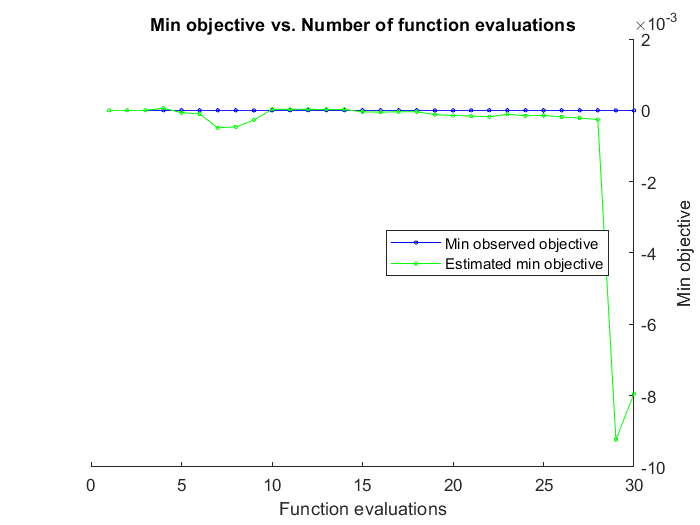


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 92.3354 seconds.
Total objective function evaluation time: 48.7932

Best observed feasible point:
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    ____________    ______________    ____________________

         1              61              gdi                  996         

Observed objective function value = 0
Estimated objective function value = -0.0044604
Function evaluation time = 3.8179

Best estimated feasible point (according to models):
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    ________

FaultLocationModel = fitctree(FaultPredictors,FaultLocationResponse,"OptimizeHyperparameters","all",'HyperparameterOptimizationOptions',struct('KFold',10));

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | ToSample     |
|===================================================================================================================================|
|    1 | Best   |           0 |     0.84567 |           0 |           0 |          443 |         1021 |     deviance |          996 |


|    2 | Accept |           0 |     0.78641 |           0 |           0 |            2 |         1971 |          gdi |          996 |


|    3 | Accept |           0 |     0.78801 |           0 |           0 |            2 |            4 |     deviance |          996 |


|    4 | Accept |           0 |     0.82986 |           0 |           0 |          193 |           11 |          gdi |          996 |


|    5 | Accept |           0 |     0.80051 |           0 |           0 |           17 |         1611 |     deviance |          996 |


|    6 | Accept |         0.5 |     0.43376 |           0 |   1.235e-07 |         1425 |          237 |     deviance |          996 |


|    7 | Accept |           0 |     0.77304 |           0 | -4.1548e-06 |            9 |           26 |          gdi |          996 |


|    8 | Accept |           0 |     0.78676 |           0 | -7.1246e-06 |           50 |          731 |          gdi |          996 |


|    9 | Accept |           0 |     0.73158 |           0 | -8.4926e-06 |            4 |          157 |          gdi |          996 |


|   10 | Accept |         0.5 |     0.40933 |           0 |  1.6014e-06 |         1488 |            1 |     deviance |          996 |


|   11 | Accept |           0 |     0.73362 |           0 |  -6.076e-06 |          215 |            1 |     deviance |          996 |


|   12 | Accept |           0 |     0.74288 |           0 | -8.1198e-06 |            6 |            1 |     deviance |          996 |


|   13 | Accept |           0 |     0.69383 |           0 |  -8.271e-06 |          640 |            4 |          gdi |          996 |


|   14 | Accept |           0 |     0.73501 |           0 | -1.0945e-05 |           50 |            1 |     deviance |          996 |


|   15 | Accept |         0.5 |     0.45843 |           0 |  2.8192e-06 |         1497 |         1223 |          gdi |          996 |


|   16 | Accept |           0 |     0.96944 |           0 | -1.8133e-05 |          399 |          355 |          gdi |          996 |


|   17 | Accept |           0 |     0.97588 |           0 | -2.3365e-05 |           22 |            1 |          gdi |          996 |


|   18 | Accept |           0 |     0.79961 |           0 | -3.3892e-05 |           99 |         2474 |          gdi |          996 |


|   19 | Accept |           0 |     0.80169 |           0 | -3.5961e-05 |            1 |         2818 |     deviance |          996 |


|   20 | Accept |           0 |     0.85665 |           0 | -3.9025e-05 |            1 |            1 |          gdi |          996 |


|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | ToSample     |
|===================================================================================================================================|
|   21 | Accept |           0 |     0.75791 |           0 | -4.6769e-05 |           98 |            2 |     deviance |          996 |


|   22 | Accept |           0 |     0.75661 |           0 | -5.8317e-05 |           10 |            1 |     deviance |          996 |


|   23 | Accept |           0 |     0.88676 |           0 | -8.7643e-05 |          323 |            1 |     deviance |          996 |


|   24 | Accept |           0 |     0.81762 |           0 | -7.2404e-05 |           30 |            1 |     deviance |          996 |


|   25 | Accept |           0 |     0.83251 |           0 | -0.00012995 |          231 |         2832 |     deviance |          996 |


|   26 | Accept |           0 |     0.78658 |           0 | -0.00014515 |            3 |         2996 |     deviance |          996 |


|   27 | Accept |           0 |     0.74905 |           0 | -0.00016001 |           14 |         2976 |          gdi |          996 |


|   28 | Accept |           0 |      0.7328 |           0 |  -0.0079072 |          526 |            3 |          gdi |          996 |


|   29 | Accept |           0 |     0.75127 |           0 |  -0.0078422 |            6 |         2916 |          gdi |          996 |


|   30 | Accept |           0 |     0.88423 |           0 |  -0.0077751 |           34 |         2033 |          gdi |          996 |


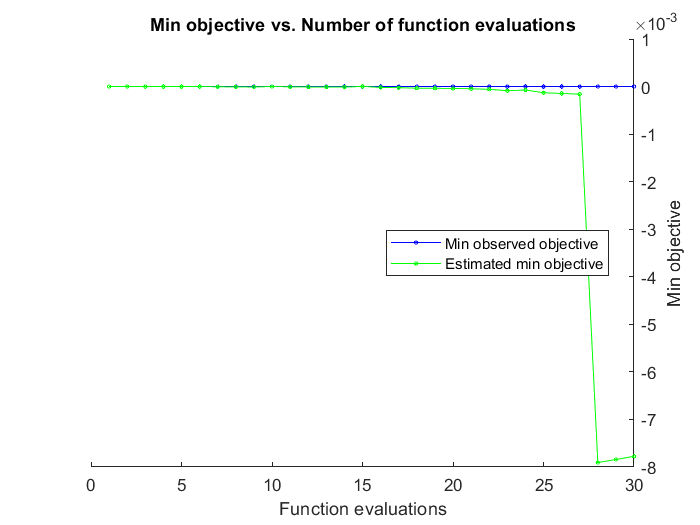


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 54.7162 seconds.
Total objective function evaluation time: 22.9073

Best observed feasible point:
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    ____________    ______________    ____________________

        443            1021           deviance               996         

Observed objective function value = 0
Estimated objective function value = 0.0056195
Function evaluation time = 0.84567

Best estimated feasible point (according to models):
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    ________

FaultTypeModel = fitctree(FaultPredictors,FaultTypeResponse,"OptimizeHyperparameters","all",'HyperparameterOptimizationOptions',struct('KFold',10));

save("C:\Users\USER\OneDrive\Escritorio\USAID\OpenDSS\13Bus\FaultModels\FaultLocationModel.mat","FaultLocationModel");
save("C:\Users\USER\OneDrive\Escritorio\USAID\OpenDSS\13Bus\FaultModels\FaultTypeModel.mat","FaultTypeModel");

Prueba con dataset de pruebas

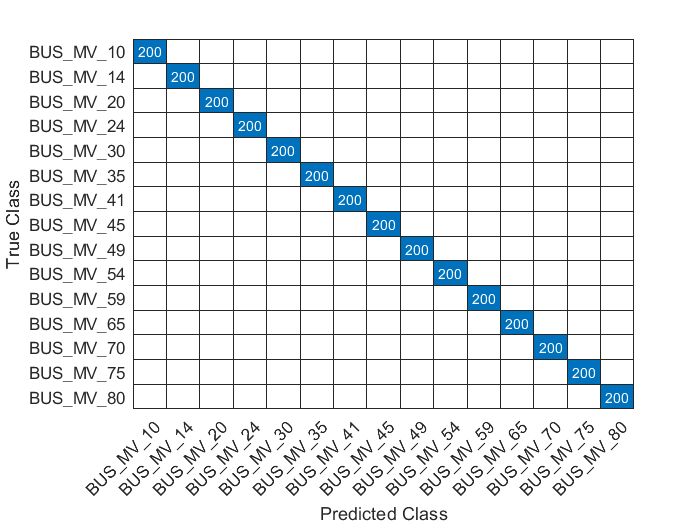

FaultTestLocationResponse = FaultLocationModel.predict(FaultTestPredictors);
FaultTestTypeResponse = FaultTypeModel.predict(FaultTestPredictors);

confusionchart(FaultTestLocation, FaultTestLocationResponse)

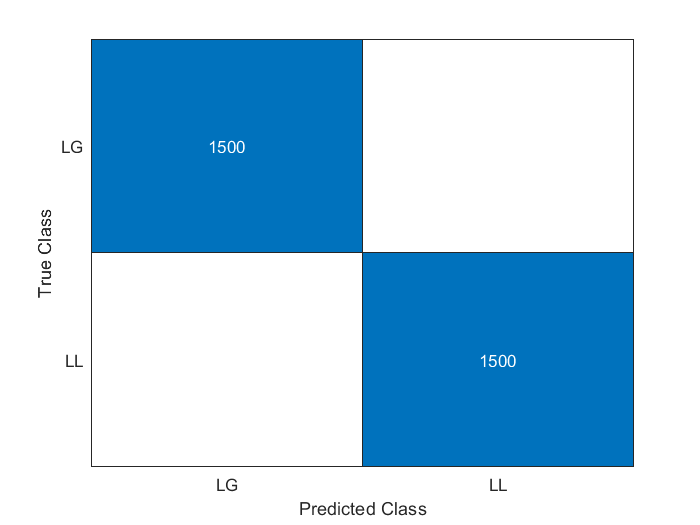

confusionchart(FaultTestType, FaultTestTypeResponse)

Predictores

LocationImportance = FaultLocationModel.predictorImportance();
nnz(LocationImportance) %numero de predictores

ans = 13

LocationImportant = FaultLocationModel.PredictorNames(LocationImportance > 0)

LocationImportant = 1×13 cell array
    {'VAngle1_LINE_4_5'}    {'VAngle1_LINE_10_11'}    {'VAngle2_LINE_14_15'}    {'I1_LINE_14_16'}    {'I1_LINE_14_41'}    {'I2_LINE_14_41'}    {'VAngle3_LINE_20_21'}    {'VAngle1_LINE_41_42'}    {'VAngle2_LINE_45_47'}    {'I1_LINE_47_49'}    {'VAngle1_LINE_54_55'}    {'I2_LINE_58_59'}    {'VAngle3_LINE_65_66'}



TypeImportance = FaultTypeModel.predictorImportance();
nnz(TypeImportance) %numero de predictores

ans = 1

TypeImportant = FaultTypeModel.PredictorNames(TypeImportance > 0)

TypeImportant = 1×1 cell array
    {'I1_LINE_4_5'}
